# Load Data and Track parameter

track_data = readmatrix('/Users/allen/Documents/Documents local/Supermileage_2024/Urban simulation/Track information/sem_2023_us.csv');
x = track_data(:, 1);
y = track_data(:, 2);
z = track_data(:, 3);


## 2D Track Visualization

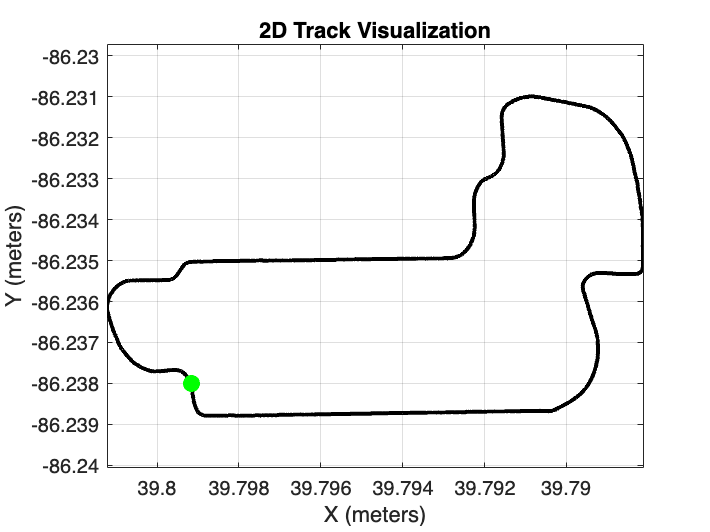

figure;
plot(x, y, 'k-', 'LineWidth', 2); % 2D track plot
hold on;
plot(x(1), y(1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % Starting point
grid on;
title('2D Track Visualization');
xlabel('X (meters)');
ylabel('Y (meters)');
axis equal; % Maintain aspect ratio

set(gca, 'XDir', 'reverse'); % Reverse the direction of the X-axis


disp(['X range: ', num2str(min(x)), ' to ', num2str(max(x))]);

X range: 39.7881 to 39.8012


disp(['Y range: ', num2str(min(y)), ' to ', num2str(max(y))]);

Y range: -86.2388 to -86.231


disp(['Z range: ', num2str(min(z)), ' to ', num2str(max(z))]);

Z range: 218.9818 to 222.7558


% figure;
% hold on; grid on; axis equal;
% 
% % Define track width parameters
% straight_width = 15; 
% turn_width = 18; 
% 
% % Compute direction vectors along the track
% theta = atan2(diff([y, y(end)]), diff([x, x(end)])); % Ensure full size
% 
% % Assign width dynamically: straight = 15m, turn = 18m
% is_turn = [abs(diff(theta)) > 0.05, false]; % Detect turns (append false to match size)
% track_width = straight_width * ~is_turn + turn_width * is_turn; % Assign width dynamically
% 
% % Compute left and right boundaries
% x_left = x - (track_width/2) .* cos(theta + pi/2);
% y_left = y - (track_width/2) .* sin(theta + pi/2);
% x_right = x + (track_width/2) .* cos(theta + pi/2);
% y_right = y + (track_width/2) .* sin(theta + pi/2);
% 
% % Ensure all arrays are column vectors for correct concatenation
% x_left = x_left(:); y_left = y_left(:);
% x_right = x_right(:); y_right = y_right(:);
% 
% % Plot track centerline
% plot(x, y, 'k-', 'LineWidth', 2);
% 
% % Plot track boundaries using fill()
% fill([x_left; flipud(x_right)], [y_left; flipud(y_right)], [0.7, 0.7, 0.7], ...
%     'EdgeColor', 'none', 'FaceAlpha', 0.5);
% 
% % Plot start point
% plot(x(1), y(1), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); 
% 
% % Formatting
% title('2D Track Visualization with Width');
% xlabel('X (meters)');
% ylabel('Y (meters)');
% set(gca, 'XDir', 'reverse'); % Reverse X-axis
% legend('Track Centerline', 'Track Area', 'Start Point');
% 
% % Display ranges
% disp(['X range: ', num2str(min(x)), ' to ', num2str(max(x))]);
% disp(['Y range: ', num2str(min(y)), ' to ', num2str(max(y))]);







## Scale Factors and 3D Track Visualisation

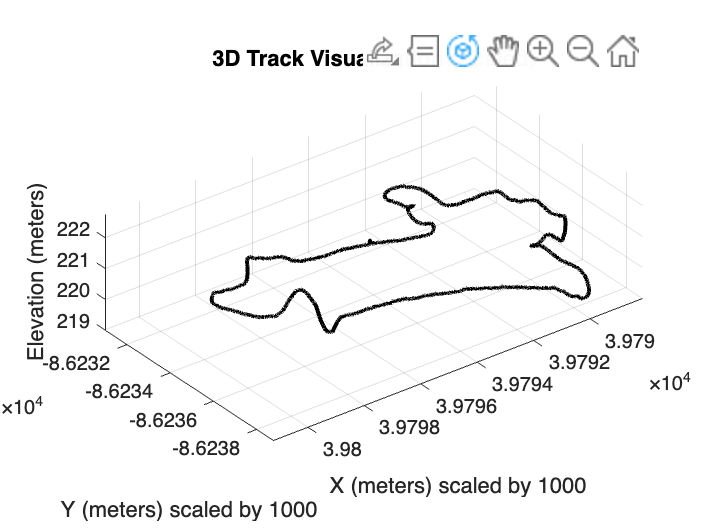

scale_factor = 1000; % Adjust based on your needs
x_scaled = x * scale_factor;
y_scaled = y * scale_factor;

% Plot the Scaled 3D Track
figure;
plot3(x_scaled, y_scaled, z, 'k-', 'LineWidth', 2); % Plot the 3D track
grid on;
title('3D Track Visualization (Scaled)');
xlabel(['X (meters) scaled by ', num2str(scale_factor)]);
ylabel(['Y (meters) scaled by ', num2str(scale_factor)]);
zlabel('Elevation (meters)');

set(gca, 'XDir', 'reverse'); % Reverse the direction of the X-axis

% Set Axis Limits
xlim([min(x_scaled), max(x_scaled)]);
ylim([min(y_scaled), max(y_scaled)]);
zlim([min(z), max(z)]);
axis equal; % Maintain aspect ratio
rotate3d on; % Enable interactive rotation

Adding width to both 2D and 3D tracks